# Homework #1

### Tasks

data = readtable("cleveland_data_revised.xlsx");

% below code works for original data set
%[num, txt] = xlsread("clevelanddata_dec2019.xlsx");

size(data)   %total rows and columns

ans =    303    14


sum(ismissing(data),"all")   %find total # of missing values

ans = 6

Find individuals with max HR and cholest

[M,I] = max(data.maxHR)

M = 202

I = 133

[M1,I1] = max(data.cholest)

M1 = 564

I1 = 153

Find avg BP and HR for individuals with and withouot heart disease

 BP1 = mean(data.restingBP(data.diseaseSeverity>0))

BP1 = 134.5683

HR1 = mean(data.maxHR(data.diseaseSeverity>0))

HR1 = 139.2590

BP2 = mean(data.restingBP(data.diseaseSeverity==0))

BP2 = 129.2500

HR2 = mean(data.maxHR(data.diseaseSeverity==0))

HR2 = 158.3780

**Diagnosis of heart disease: BP = 134.6, HR = 139.26.**

**No heart disease: BP = 129.3, HR = 158.38.**

Heart disease involves narrowed or blocked blood vessels, which restricts blood flow and thereby increase blood pressure. Our data set confirms this trend. However, the patients in the data set without heart disease have a higher heart rate on average compared to those with heart disease. This is surprising because heart disease is typically associated with an increased heart rate.

### Do the following:

Plot BP vs Cholesterol and differentiate normal vs disease

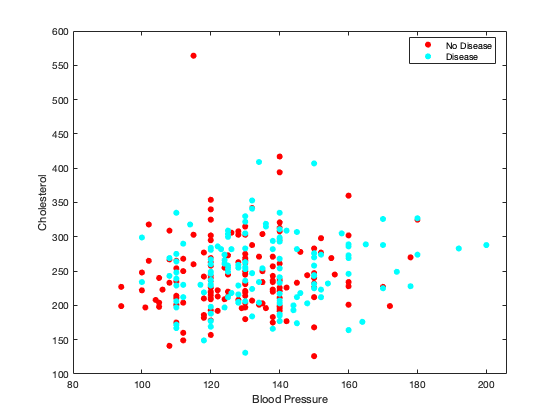

disease = data.diseaseSeverity > 0;   % Create new var for diseased (1 = diseased)

figure;
gscatter(data.restingBP, data.cholest, disease)
legend('No Disease','Disease')
xlabel('Blood Pressure')
ylabel('Cholesterol')

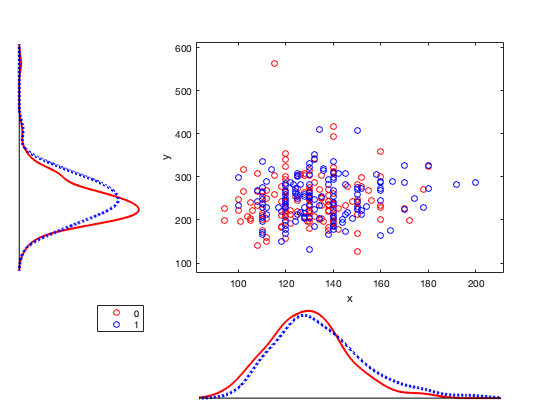

figure;
scatterhist(data.restingBP, data.cholest, "Group", disease,...
    "Color", ["r","b"], "Legend","on", "Kernel","on");

Distribution of HR and ECG ST depression

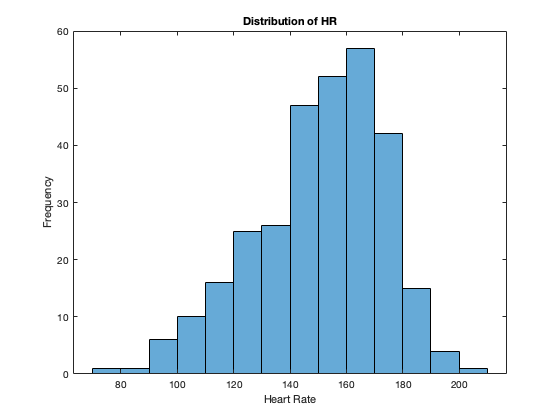

figure;
histogram(data.maxHR)
xlabel('Heart Rate')
ylabel('Frequency')
title('Distribution of HR')

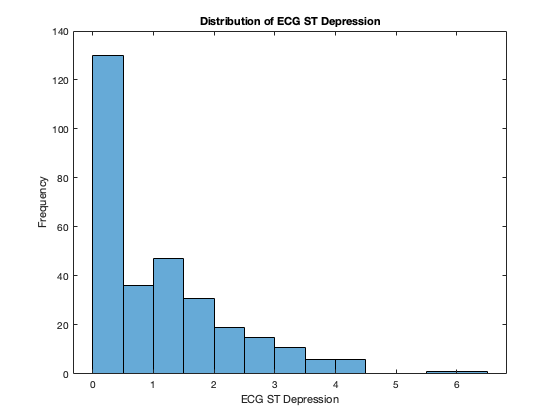

figure;
histogram(data.ECGDepression)
xlabel('ECG ST Depression')
ylabel('Frequency')
title('Distribution of ECG ST Depression')

Plot first 10 variables using gplotmatrix

% Need below lines for original dataset
%data.thaliumTest = cell2mat(data.thaliumTest);
%data.fluoroscopy = cell2mat(data.flourosopy);
data_10 = table2array(data(:,1:10));
vars_10 = data.Properties.VariableNames(1:10)

vars_10 = 1×10 cell array
    {'Age'}    {'SEX'}    {'chestPain'}    {'restingBP'}    {'cholest'}    {'highBloodSugar'}    {'ECG'}    {'maxHR'}    {'angina'}    {'ECGDepression'}


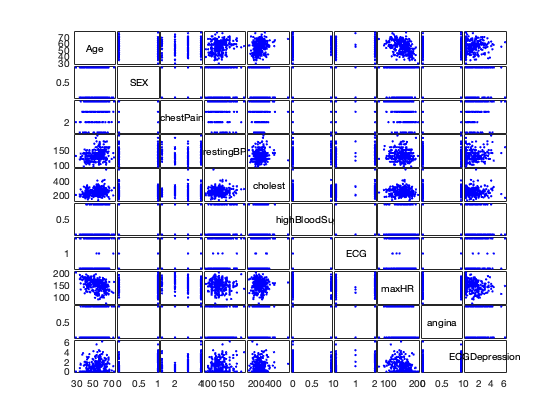

gplotmatrix(data_10,[],[],[],[],[],[],'variable',vars_10);

### Correlation

Find properties that are most and least strongly correlated with degree of heart disease

r = splitvars(table(corr(data.Variables,data.diseaseSeverity,"rows","complete")));
r.Properties.RowNames = data.Properties.VariableNames

r = 14×1 table
                         Var1  
                       ________

    Age                 0.22216
    SEX                  0.2268
    chestPain           0.40425
    restingBP           0.15962
    cholest            0.066448
    highBloodSugar      0.04904
    ECG                 0.18414
    maxHR              -0.42064
    angina              0.39161
    ECGDepression       0.50146
    slopeST             0.37469
    fluoroscopy         0.52118
    thalliumTest        0.51338
    diseaseSeverity           1


The highest correlated features are from **columns 10 (ECGDepression) and 13 (thaliumTest).**

The least correlated features are from **columns 5 (cholest) and columns 6 (highBloodSugar).**

Repeat analysis for males and females, separately. 

% extract data by sex
male = data(data.SEX==0,:);
female = data(data.SEX==1,:);

% created sorted correlation tables
r_male = splitvars(table(corr(male.Variables,male.diseaseSeverity,"rows","complete")));
r_male.Properties.RowNames = data.Properties.VariableNames;
sortrows(r_male)

ans = 14×1 table
                        Var1  
                       _______

    maxHR              -0.2667
    cholest            0.12194
    Age                0.19997
    ECG                0.22122
    highBloodSugar     0.25743
    angina             0.31179
    chestPain          0.39816
    restingBP          0.42737
    slopeST            0.44444
    ECGDepression      0.61001
    fluoroscopy        0.64332
    thalliumTest       0.70741
    diseaseSeverity          1
    SEX                    NaN


Highest correlated features for males are **thaliumTest **and** fluoroscopy.**

Lowest correlated features for males are **age **and** cholesterol.**

r_female = splitvars(table(corr(female.Variables,female.diseaseSeverity,"rows","complete")));
r_female.Properties.RowNames = data.Properties.VariableNames;
sortrows(r_female)

ans = 14×1 table
                         Var1   
                       _________

    maxHR               -0.46663
    highBloodSugar     -0.035998
    restingBP           0.071526
    cholest              0.12184
    ECG                  0.16674
    Age                  0.27428
    slopeST              0.35339
    angina               0.39333
    thalliumTest         0.40437
    chestPain            0.41813
    ECGDepression        0.45091
    fluoroscopy          0.47118
    diseaseSeverity            1
    SEX                      NaN


Highest correlated features for females are** max HR **and** fluoroscopy.**

Lowest correlated features for females are r**esting BP **and** high blood sugar.**

Find pairwaise rank correlations between all 14 variables and visualize with heatmap

% remove missing data (occurs in columns 12 and 13)
data_rm = rmmissing(data);
rank = corr(data_rm.Variables,"type","Spearman")

rank =     1.0000   -0.0954    0.1327    0.2996    0.1834    0.1246    0.1482   -0.3926    0.0887    0.2519    0.1735    0.3818    0.1268    0.2424
   -0.0954    1.0000    0.0412   -0.0636   -0.1534    0.0389    0.0339   -0.0563    0.1436    0.1123    0.0271    0.1031    0.3753    0.2598
    0.1327    0.0412    1.0000    0.0005    0.0732   -0.0654    0.0921   -0.3807    0.4242    0.2449    0.2042    0.2636    0.3103    0.4812
    0.2996   -0.0636    0.0005    1.0000    0.1392    0.1555    0.1458   -0.0468    0.0524    0.1558    0.0890    0.0783    0.1114    0.1411
    0.1834   -0.1534    0.0732    0.1392    1.0000    0.0170    0.1625   -0.0348    0.0832    0.0241   -0.0034    0.1348    0.0038    0.1044
    0.1246    0.0389   -0.0654    0.1555    0.0170    1.0000    0.0688   -0.0102   -0.0009    0.0262    0.0313    0.1436    0.0546    0.0354
    0.1482    0.0339    0.0921    0.1458    0.1625    0.0688    1.0000   -0.1052    0.0819    0.1044    0.1396    0.1277    0.0153    0.1806
   -0.

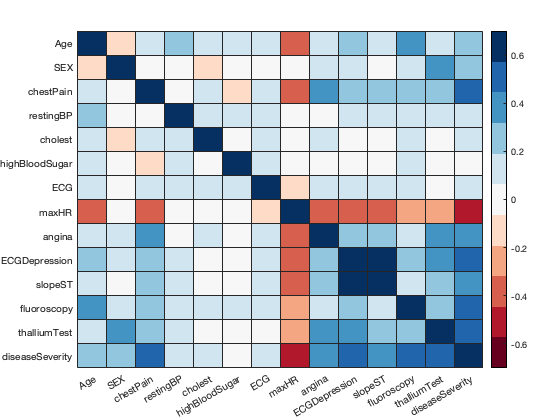

figure;
heatmap(rank,"XDisplayLabels",data_rm.Properties.VariableNames,"YDisplayLabels",...
    data_rm.Properties.VariableNames,"Colormap",flipud(redbluecmap),'ColorLimits',[-0.7 0.7]);

It appears that several features are negatively correlated with Feature 8 (max heart rate). This suggests that the higher a patient's heart rate, the lower their chances of cardiovascular complications. There are several features with strong positive correlations with heart disease diagnosis. For example, heart rate diagnosis seems to increase with thaliumTest and number of major vessels colored by fluoroscopy.

### Box plots

Compare max HR, ECG ST depression, resting BP vs 4 levels of heart disease

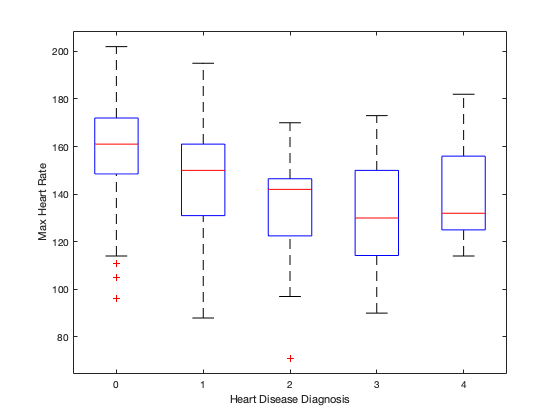

figure;
boxplot(data.maxHR, data.diseaseSeverity)
xlabel('Heart Disease Diagnosis')
ylabel('Max Heart Rate')

It appears that heart rate actually decreases with the severity of the patient's heart disease diagnosis, until the diagnosis reaches level 4, where the average HR increases again.

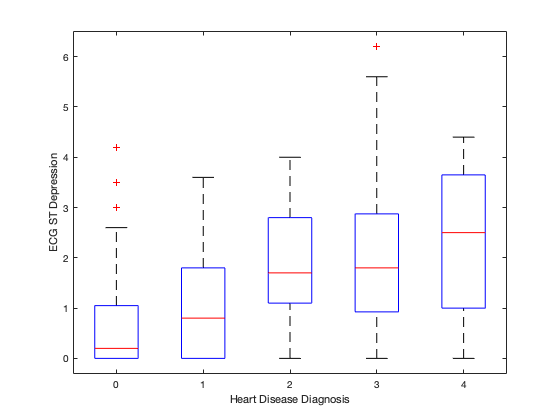

figure;
boxplot(data.ECGDepression, data.diseaseSeverity)
xlabel('Heart Disease Diagnosis')
ylabel('ECG ST Depression')

ECG ST depression clearly increases with heart disease diagnosis.

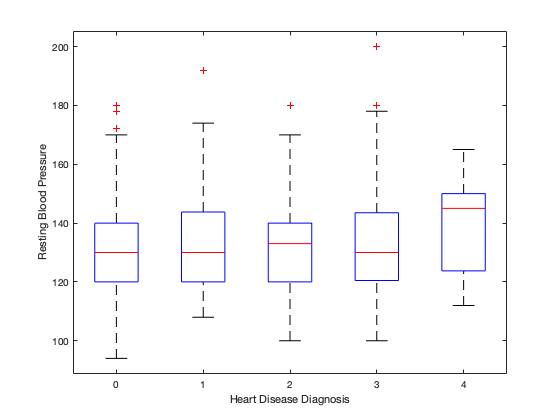

figure;
boxplot(data.restingBP, data.diseaseSeverity)
xlabel('Heart Disease Diagnosis')
ylabel('Resting Blood Pressure')

It appears that resting blood pressure is not strongly related to heart disease diagnosis. Although, patients with a level 4 diagnosis do have a higher mean BP.

Use subplot to make 10 boxplots in a 4x3 grid. Compare first 10 variables vs 2 levels of heart disease (absent, present).

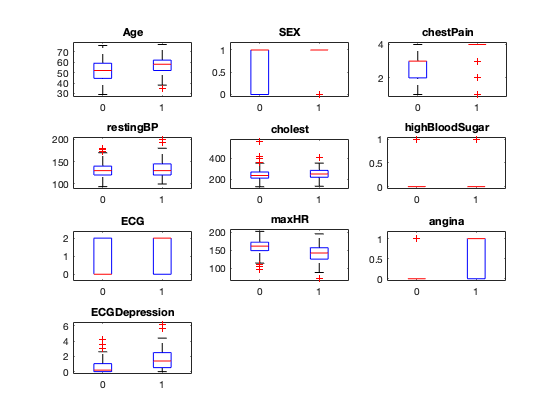

figure;
for i = 1:10
    subplot(4,3,i)
    boxplot(data.(i),disease)
    title(data.Properties.VariableNames(i))
end

- those with heart disease (HD) tend to be older

- median resting blood pressure is not different, but those with HD do have a larger range of BP values

- median heart rate is lower for patients with HD

- ECG ST depression is significantly higher for patients with HD